this try using the paper "Jigsaw Puzzle Solver Write Up"

by: Jennifer Liu, Aaron Cote

link:

[https://drive.google.com/file/d/1q1ahRtAYi71gAS5-2J3XmB8htGU_8Wf6/view](https://drive.google.com/file/d/1q1ahRtAYi71gAS5-2J3XmB8htGU_8Wf6/view)

try to flow thier steps:

first step: segmentation

% RGB=(imread("..\img\pzl_12_p2.jpg"));
% imshow(RGB)
% ImgGray = double(im2gray(RGB));
% I = (ImgGray - min(ImgGray(:)))/(max(ImgGray(:)) - min(ImgGray(:)));
% imshow(I)
% I=medfilt2(I);
% imshow(I)
extent_filter=0.9;
dialtion_size1=2;
dialtion_size2=3;

using soble with low threshold

note: running time

% BW = edge(I,'sobel',0.01,'both','nothinning');
% imshow(BW)

clean the noise using median filter

% BW=medfilt2(BW);
% imshow(BW)
% dial = imdilate(BW,strel("rectangle",[dialtion_size1,dialtion_size1]));%**
% % extent = bwpropfilt(dial, 'Extent', [0, extent_filter]);
% 
% % dial = imdilate(extent,strel("rectangle",[dialtion_size2,dialtion_size2]));%**

% imshow(dial)
% mask = imfill(double(dial),8,"holes");
% imshow(mask)
% I_R(mask==1)=I(:,:,1);
% imhist(I1)

NOTE: Tomer use in this section algoritem to seperate the pieces..

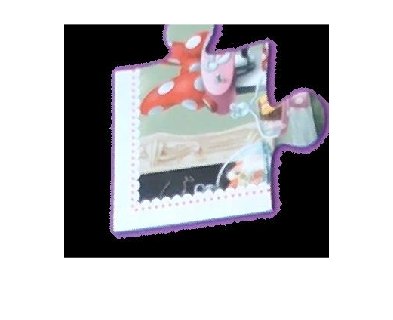

extent_filter=0.9;
dialtion_size1=2;
dialtion_size2=3;
N=9;

RGB=(imread("..\image_pices_test\p_7.jpg"));
imshow(RGB)

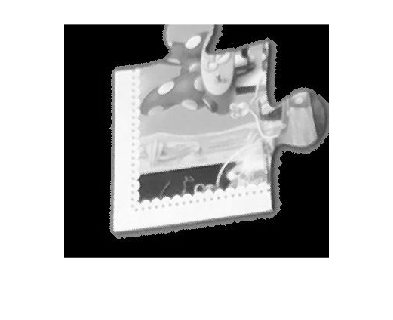

ImgGray = double(im2gray(RGB));
I = (ImgGray - min(ImgGray(:)))/(max(ImgGray(:)) - min(ImgGray(:)));
imshow(I)

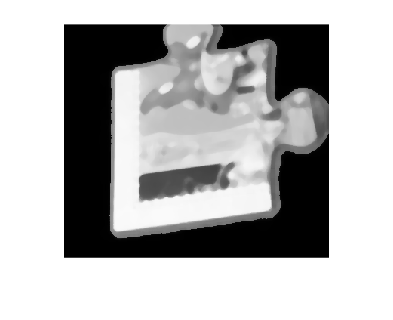


I=medfilt2(I,[N,N]);
imshow(I);

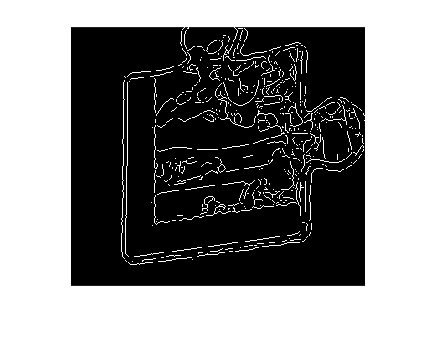

BW = edge(I,'sobel',0.01,'both','thinning');
imshow(BW)

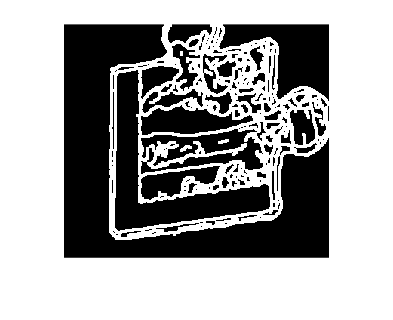

dial = imdilate(BW,strel("rectangle",[dialtion_size1,dialtion_size1]));%**
extent = bwpropfilt(dial, 'Extent', [0, extent_filter]);

dial = imdilate(extent,strel("rectangle",[dialtion_size2,dialtion_size2]));%**
imshow(dial)

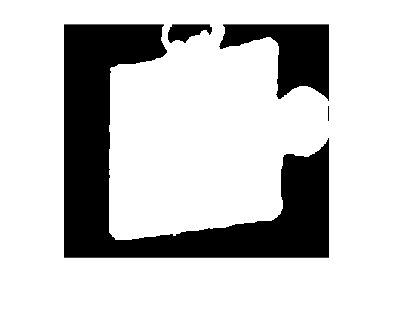

mask = imfill(double(dial),8,"holes");
imshow(mask)

center of mass:

figure;
imshow(mask);
hold on
props = regionprops(true(size(mask)), mask, 'WeightedCentroid');
plot(props.WeightedCentroid(1),props.WeightedCentroid(2),'*');
hold on

center of image:

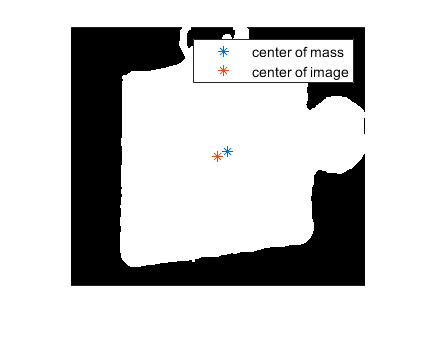

x_center=size(mask,2)/2;
y_center=size(mask,1)/2;
plot(x_center,y_center,'*')
legend('center of mass', 'center of image')
hold off

devide the image to 4. using the senter of mass as the center

BW = edge(mask);
line_width=0;
x1_start=1; y1_start=props.WeightedCentroid(2)-line_width; x1_end=size(I,2); y1_end=props.WeightedCentroid(2)+line_width;
x2_start=props.WeightedCentroid(1)+line_width; y2_start=1; x2_end=props.WeightedCentroid(1)+line_width; y2_end=size(I,1);
figure
imshow(I)
% line([x1_start x1_end],[y1_start y1_end]);
% line([x2_start x2_end],[y2_start y2_end]);
line([1,size(mask,2)],[y_center-line_width,y_center+line_width],'Color','red','LineStyle','--');
line([x_center-line_width,x_center+line_width],[1,size(mask,1)],'Color','red','LineStyle','--');
hold on

try using the harris algotirhem to find the corners

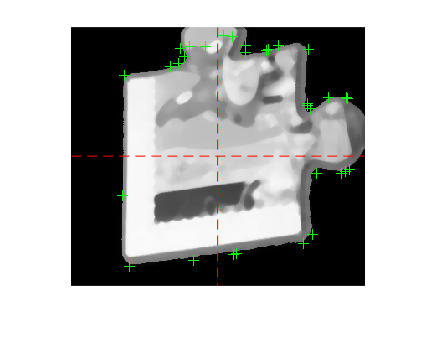

minQuality=0.35;
filterSize=9;
corners_harris = detectHarrisFeatures(BW,'MinQuality',minQuality,"FilterSize",filterSize);
plot(corners_harris);
hold on
% alpha1=(55*pi)/180;
% line([y_center,y_center+y_center*sin(alpha1)],[1,x_center])  
hold off

% Q1=detectHarrisFeatures(obw,'MinQuality',minQuality,"FilterSize",filterSize);%,"ROI",[size(maxk,2)-x_center,1,]

now convert the location of the graph to polar regard to the center of mass

Location_cart=corners_harris.Location;
x_location_center=Location_cart(:,1)-x_center;
y_location_center=Location_cart(:,2)-y_center;
[theta_center, rho_center]=cart2pol(x_location_center,y_location_center);


try2: sepert

NOT good try:

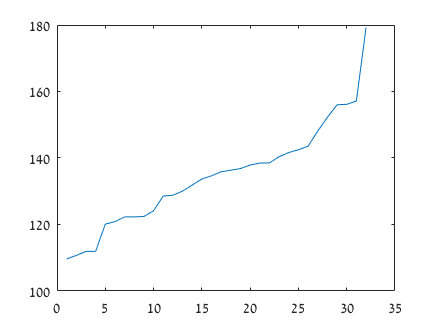


x_location_center_of_mass=Location_cart(:,1)-props.WeightedCentroid(1);
y_location_center_of_mass=Location_cart(:,2)-props.WeightedCentroid(2);
[theta_mass, rho_mass]=cart2pol(x_location_center_of_mass,y_location_center_of_mass);
serted_distance=sort(rho_mass);
figure
plot(serted_distance)

try to find the corner. my assamption is that the corner are in the same distace from the center of mass. 

i use gradient to find the chnge betwin the rdius

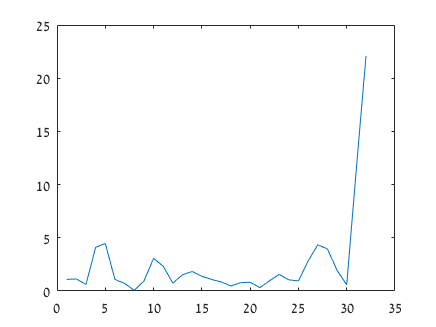

fx=gradient(serted_distance);
figure
plot(fx)

using convolution to find the sum of the 4 closet radius

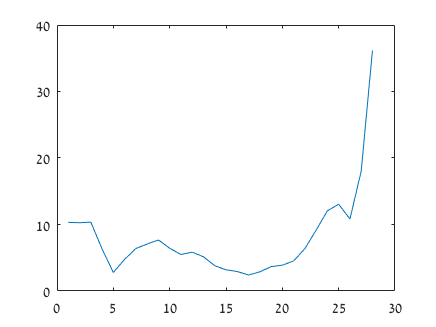

sumfx=zeros(length(fx)+3,1);
sumfx(1:length(fx))=sumfx(1:length(fx))+fx;
sumfx(2:length(fx)+1)=sumfx(2:length(fx)+1)+fx;
sumfx(3:length(fx)+2)=sumfx(3:length(fx)+2)+fx;
sumfx(4:length(fx)+3)=sumfx(4:length(fx)+3)+fx;
sumfx=sumfx(5:end-3);

figure
plot(sumfx)